clc 
clear
addpath("Functions\")
yalmip('clear')

**State Space formulation and discretization**

syms beta(t) tau w
linBeta = deg2rad(90);%% Starh with beta at 0 degrees linearization
winDir = 0;
muWind = 0.5;
[A_cont,B_cont] = Linearization_Wind(linBeta,beta,tau,winDir,w,muWind); 
% 
 % C_cont=[0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0;
 %         0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0;
 %         0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0;
 %         0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0;
 %         0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
 %         0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0;
 %         0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0;]

  C_cont=eye(length(A_cont));
C_cont(5,:) = [] 

C_cont =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0    

D =0;


l=18;

h = 0.2; % Discrete time step,
[A,B,C] = Forward_BackEuler(A_cont,B_cont,C_cont,h)

A =     1.0000         0         0    0.0000   -0.0001         0    0.0000   -0.0000    0.1973   -0.0000   -0.0000    0.0000   -0.0000         0    0.0000   -0.0000    0.0011
         0    1.0000         0    0.0150    0.0000         0   -0.0000    0.0003   -0.0000    0.1984    0.0000    0.0015    0.0000         0   -0.0000    0.0000    0.0000
         0         0    1.0000    0.0003   -0.0000         0   -0.0002    0.0000    0.0000    0.0000    0.1982    0.0000   -0.0000         0   -0.0000    0.0000   -0.0000
         0         0         0    0.9981    0.0000         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.1976    0.0000         0    0.0000   -0.0000    0.0000
         0         0         0   -0.1556    1.0000         0   -0.0000    0.0000   -0.0144    0.0000    0.0000   -0.0152    0.1999         0   -0.0000    0.0000    0.0061
         0         0         0         0         0    1.0000         0         0         0         0         0         0         0    0.2000 

B = 1.0e-03 *

    0.0075   -0.0000   -0.0000   -0.0000    0.0075   -0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0075    0.0000   -0.0000    0.0000    0.0075    0.0000
   -0.0000    0.0043    0.0000    0.0043   -0.0000    0.0043    0.0000    0.0043
    0.0000   -0.0000   -0.0004   -0.0000    0.0000   -0.0000   -0.0004   -0.0000
    0.0415    0.0000    0.0000    0.0000    0.0415    0.0000    0.0000    0.0000
         0    0.0001         0         0         0   -0.0001         0         0
         0         0         0    0.0001         0         0         0   -0.0001
    0.0000         0   -0.0000         0   -0.0000         0    0.0000         0
    0.0747   -0.0000   -0.0000   -0.0000    0.0747   -0.0000   -0.0000   -0.0000
    0.0000    0.0003    0.0751    0.0003   -0.0000    0.0003    0.0751    0.0003


C =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     1   


sys = ss(A,B,C,D);
n = length(A);

simTime = 60/h;

**Wind Paramaters**

muw = .5;

ti = 0.05; %turbulence itencity

CV = ti*muw;

 
%Turbulent part
Wt= zeros(1,simTime);
wp = (muw*pi)/(2*340.2);
at = exp(-wp*h)

at = 0.9995

stdt= (ti *muw*sqrt(1-at^2));

%Slow Part
q = 2^2/600 ; %slow part changinf by 2m/s over 10 min.
stdw = sqrt(h*q);
Ws= zeros(1,simTime);
Ws(50) = 0.5;


W = zeros(1,simTime)

W =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


**MPC Formulation**


ref =0;
Hp = 30;
Hu = 1;
%Lifting the dynamics to be expressed in terms of delta u.
[ALift, BuLift, BduLift, Psi, Upsilon_B, Theta] = MPCLift(A, B, C ,Hp, Hu)

Condition of:
 Psi: 2890.988914
 Upsilon: 31226082849295308.000000 
 Theta: 31226082849295308.000000

ALift =     1.0000         0         0    0.0000   -0.0001         0    0.0000   -0.0000    0.1973   -0.0000   -0.0000    0.0000   -0.0000         0    0.0000   -0.0000    0.0011
         0    1.0000         0    0.0150    0.0000         0   -0.0000    0.0003   -0.0000    0.1984    0.0000    0.0015    0.0000         0   -0.0000    0.0000    0.0000
         0         0    1.0000    0.0003   -0.0000         0   -0.0002    0.0000    0.0000    0.0000    0.1982    0.0000   -0.0000         0   -0.0000    0.0000   -0.0000
         0         0         0    0.9981    0.0000         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.1976    0.0000         0    0.0000   -0.0000    0.0000
         0         0         0   -0.1556    1.0000         0   -0.0000    0.0000   -0.0144    0.0000    0.0000   -0.0152    0.1999         0   -0.0000    0.0000    0.0061
         0         0         0         0         0    1.0000         0         0         0         0         0         0         0    0.2

BuLift =     0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0    0.0000         0         0         0   -0.0000         0         0
         0         0         0    0.0000         0         0         0   -0.0000
    0.0000         0   -0.0000         0   -0.0000         0    0.0000         0
    0.0001   -0.0000   -0.0000   -0.0000    0.0001   -0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0001    0.0000   -0.0000    0.0000    0.0001    0.0000


BduLift =     0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0    0.0000         0         0         0   -0.0000         0         0
         0         0         0    0.0000         0         0         0   -0.0000
    0.0000         0   -0.0000         0   -0.0000         0    0.0000         0
    0.0001   -0.0000   -0.0000   -0.0000    0.0001   -0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0001    0.0000   -0.0000    0.0000    0.0001    0.0000


Psi =     1.0000         0         0    0.0000   -0.0001         0    0.0000   -0.0000    0.1973   -0.0000   -0.0000    0.0000   -0.0000         0    0.0000   -0.0000    0.0011
         0    1.0000         0    0.0150    0.0000         0   -0.0000    0.0003   -0.0000    0.1984    0.0000    0.0015    0.0000         0   -0.0000    0.0000    0.0000
         0         0    1.0000    0.0003   -0.0000         0   -0.0002    0.0000    0.0000    0.0000    0.1982    0.0000   -0.0000         0   -0.0000    0.0000   -0.0000
         0         0         0    0.9981    0.0000         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.1976    0.0000         0    0.0000   -0.0000    0.0000
         0         0         0         0         0    1.0000         0         0         0         0         0         0         0    0.2000         0         0         0
         0         0         0         0         0         0    1.0000         0         0         0         0         0         0         

Upsilon_B =     0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
         0    0.0000         0         0         0   -0.0000         0         0
         0         0         0    0.0000         0         0         0   -0.0000
    0.0000         0   -0.0000         0   -0.0000         0    0.0000         0
    0.0001   -0.0000   -0.0000   -0.0000    0.0001   -0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0001    0.0000   -0.0000    0.0000    0.0001    0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000


Theta =     0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
         0    0.0000         0         0         0   -0.0000         0         0
         0         0         0    0.0000         0         0         0   -0.0000
    0.0000         0   -0.0000         0   -0.0000         0    0.0000         0
    0.0001   -0.0000   -0.0000   -0.0000    0.0001   -0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0001    0.0000   -0.0000    0.0000    0.0001    0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000



p = size(B,2);
m = size(C,1)

m = 16



%Tune values from Q and R 
QLift = 100*eye(Hp*m);
RLift = 1*eye(Hu*p);
rho =ones(1,2);
rho(1) = 10

rho =     10     1


rho(2) = 10

rho =     10    10




duPlot = zeros(p,simTime);
Xplant = zeros(n,simTime);
Yplant = zeros(n,simTime);
x = zeros(n,simTime);
u = zeros(p,simTime);


du = sdpvar(8*Hu,1);
slack = sdpvar(2,1);

 Tau = [ones(Hp*m,1)]

Tau =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



% for i=1:Hp
%     Tau((i-1)*m+1:i*m) = [0;0;15;0;0];
% end
constraints = [];
% for i=1:Hp
%     Tau((i-1)*m+1:i*(m)) = [0;0;15;0;30;0;0];
% end

for i=1:Hp
    Tau((i-1)*m+1:i*(m)) = [0;30;15;0;0;0;0;0;0;0;0;0;0;0;0;0];
end
% Xplant(:,1) = [0 0 0 deg2rad(10) 0 0 0 0]';
Xplant(:,1) = [0 0 15 deg2rad(0) deg2rad(90) 0 0 0 0 0 0 0 0 0 0 0 0]';


noise = 1;  
f = waitbar(0,'Please wait...');
tic

lin_count = 0

lin_count = 0


for i=2:(simTime)
    % Calculate the Plant

    %Wind speed stuff
   
    if i > 50 && i < 250

        et = normrnd(0,stdw);
        Ws(i) = Ws(i-1)+ et;

        es = normrnd(0,stdt^2);
        Wt(i) = at * Wt(i-1)+ es;

        W(i)  = Ws(i) + Wt(i);

        if W(i) <=0
            W(i) = 0;
        end
    end
   % Xplant(:,i) = A * Xplant(:,i-1) + B*u(:,i-1) + W*w(i-1);
    Xplant(17,i-1) = W(i);
    Xplant(:,i) = A * Xplant(:,i-1) + B*u(:,i-1);

    if abs(linBeta-Xplant(5,i))>deg2rad(0.2)
        
        lin_count= lin_count+1;
        waitbar(i/simTime,f, sprintf('New linearization point. Total: %i', lin_count));
       linBeta = Xplant(5,i);
       [A_cont,B_cont] = Linearization_Wind(linBeta,beta,tau,winDir,w,muWind); 
       [A,B,C] = Forward_BackEuler(A_cont,B_cont,C_cont,h);
       [ALift, BuLift, BduLift, Psi, Upsilon, Theta] = MPCLift(A, B, C ,Hp, Hu);
    end
    xopt = Xplant(:,i); % Seh the current state as the starting point for the optimization.
    % xopt = y0';

    %z = Psi * xopt + Upsilon_B * u(:,i-1)+ Upsilon_W * w(i) + Theta * du;

    z = Psi * xopt + Upsilon_B * u(:,i-1) + Theta * du;
    objective = ( (z - Tau)' * QLift * (z - Tau) + du' * RLift * du + rho * slack);
    % constraints = [abs(z(1:m:end)) <= deg2rad(10) + slack(1),abs(z(2:m:end)) <= deg2rad(2) + slack(2),abs(u(:,i-1)+du(1:p))<= [100;100;100;100;100;100;100;100],slack >= 0]
    constraints1 = [abs(z(4:m:end)) <= deg2rad(10) + slack(1),abs(z(13:m:end)) <= deg2rad(10) + slack(2),abs(u(:,i-1)+du(1:p))<= [200;200;200;200;200;200;200;200],slack >= 0]
    constraints2 = []

    ops = sdpsettings('solver','ipopt');
    ops.verbose = 0;
    % ops.verbose = 0; % makes yalmip quiet
    optimize([constraints1,constraints2],objective, ops);


    duPlot(:,i) = du(1:p);
    waitbar(i/simTime,f, sprintf('Simulating step: %i of %i',i, simTime));
    u(:,i) = u(:,i-1) + du(1:p);
    
end

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2903.869443
 Upsilon: 18193772617063172.000000 
 Theta: 18193772617063172.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2918.548884
 Upsilon: 17174647830581520.000000 
 Theta: 17174647830581520.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2940.758126
 Upsilon: 15658758083786414.000000 
 Theta: 15658758083786414.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2971.211712
 Upsilon: 14648596999179800.000000 
 Theta: 14648596999179800.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3009.997013
 Upsilon: 29373308063578700.000000 
 Theta: 29373308063578700.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3056.280952
 Upsilon: 35814282624657988.000000 
 Theta: 35814282624657988.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3107.819445
 Upsilon: 12398972672753210.000000 
 Theta: 12398972672753210.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3160.188889
 Upsilon: 19189842254047312.000000 
 Theta: 19189842254047312.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3205.677181
 Upsilon: 16072372872803956.000000 
 Theta: 16072372872803956.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3231.887127
 Upsilon: 24993449001518620.000000 
 Theta: 24993449001518620.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3220.428870
 Upsilon: 34917290646858368.000000 
 Theta: 34917290646858368.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3146.689862
 Upsilon: 12953942243558906.000000 
 Theta: 12953942243558906.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2982.317247
 Upsilon: 15621263869269858.000000 
 Theta: 15621263869269858.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2701.765835
 Upsilon: 13144931073901052.000000 
 Theta: 13144931073901052.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2292.127325
 Upsilon: 28206263539422340.000000 
 Theta: 28206263539422340.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1763.352861
 Upsilon: 44841571616414720.000000 
 Theta: 44841571616414720.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1158.425424
 Upsilon: 20203039689101340.000000 
 Theta: 20203039689101340.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 566.890932
 Upsilon: 41357654553798968.000000 
 Theta: 41357654553798968.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 148.286486
 Upsilon: 49728175814613520.000000 
 Theta: 49728175814613520.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 265.688467
 Upsilon: 37236748562347888.000000 
 Theta: 37236748562347888.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 998.739283
 Upsilon: 31121953026966348.000000 
 Theta: 31121953026966348.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2112.833367
 Upsilon: 39572491062093968.000000 
 Theta: 39572491062093968.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3081.319372
 Upsilon: 23321111066216452.000000 
 Theta: 23321111066216452.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3077.842162
 Upsilon: 52052787738366216.000000 
 Theta: 52052787738366216.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2192.812572
 Upsilon: 49921440819504752.000000 
 Theta: 49921440819504752.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1238.406928
 Upsilon: 15127564103865606.000000 
 Theta: 15127564103865606.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 574.782929
 Upsilon: 21540313442582428.000000 
 Theta: 21540313442582428.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 236.182983
 Upsilon: 42270959423828648.000000 
 Theta: 42270959423828648.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 83.124720
 Upsilon: 20038010804289936.000000 
 Theta: 20038010804289936.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 138.471142
 Upsilon: 7182359670403590.000000 
 Theta: 7182359670403590.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 236.126916
 Upsilon: 29215487862296516.000000 
 Theta: 29215487862296516.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 316.183590
 Upsilon: 20463056009763960.000000 
 Theta: 20463056009763960.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 356.030646
 Upsilon: 9853402055517850.000000 
 Theta: 9853402055517850.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 342.724758
 Upsilon: 15955885269187434.000000 
 Theta: 15955885269187434.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 281.123053
 Upsilon: 17380904178685362.000000 
 Theta: 17380904178685362.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 191.303053
 Upsilon: 25094808890356908.000000 
 Theta: 25094808890356908.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 93.487984
 Upsilon: 36157047456394320.000000 
 Theta: 36157047456394320.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 133.417520
 Upsilon: 5658303414933217.000000 
 Theta: 5658303414933217.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 329.497219
 Upsilon: 12447211831943592.000000 
 Theta: 12447211831943592.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 735.451816
 Upsilon: 37404208677894632.000000 
 Theta: 37404208677894632.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1413.798204
 Upsilon: 14815897009186160.000000 
 Theta: 14815897009186160.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2265.470291
 Upsilon: 32488897746960080.000000 
 Theta: 32488897746960080.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3004.824399
 Upsilon: 10027497384615592.000000 
 Theta: 10027497384615592.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3224.968343
 Upsilon: 24521592622476152.000000 
 Theta: 24521592622476152.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2901.908546
 Upsilon: 46499876070857080.000000 
 Theta: 46499876070857080.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2415.706477
 Upsilon: 35288090039413204.000000 
 Theta: 35288090039413204.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2040.714253
 Upsilon: 21915077996870248.000000 
 Theta: 21915077996870248.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1869.318225
 Upsilon: 51650347257934296.000000 
 Theta: 51650347257934296.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1910.179772
 Upsilon: 37169905569387352.000000 
 Theta: 37169905569387352.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2152.660964
 Upsilon: 29177397305692324.000000 
 Theta: 29177397305692324.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2559.283819
 Upsilon: 38425071160229184.000000 
 Theta: 38425071160229184.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3010.303710
 Upsilon: 14463978600000114.000000 
 Theta: 14463978600000114.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3233.336396
 Upsilon: 20911157462307756.000000 
 Theta: 20911157462307756.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2925.820198
 Upsilon: 34634368202969744.000000 
 Theta: 34634368202969744.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2154.811907
 Upsilon: 23300070433091164.000000 
 Theta: 23300070433091164.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1286.438088
 Upsilon: 29761159440760032.000000 
 Theta: 29761159440760032.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 608.077553
 Upsilon: 13846227962346470.000000 
 Theta: 13846227962346470.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 234.922135
 Upsilon: 28371944509724600.000000 
 Theta: 28371944509724600.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 74.191307
 Upsilon: 19966660023768232.000000 
 Theta: 19966660023768232.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 184.291517
 Upsilon: 9666195321353998.000000 
 Theta: 9666195321353998.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 327.222068
 Upsilon: 8386404409312083.000000 
 Theta: 8386404409312083.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 455.413431
 Upsilon: 28443699061545536.000000 
 Theta: 28443699061545536.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 527.744704
 Upsilon: 19786307332600320.000000 
 Theta: 19786307332600320.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 456.655585
 Upsilon: 18514622077850460.000000 
 Theta: 18514622077850460.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 342.119918
 Upsilon: 13988626657059180.000000 
 Theta: 13988626657059180.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 215.059729
 Upsilon: 42496956014289688.000000 
 Theta: 42496956014289688.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 97.329308
 Upsilon: 24937607103007488.000000 
 Theta: 24937607103007488.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 143.168967
 Upsilon: 9823754575168062.000000 
 Theta: 9823754575168062.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 377.108374
 Upsilon: 37672835565642696.000000 
 Theta: 37672835565642696.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 893.759587
 Upsilon: 12780810636306420.000000 
 Theta: 12780810636306420.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1777.257060
 Upsilon: 49989408598692136.000000 
 Theta: 49989408598692136.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2824.391790
 Upsilon: 16764420692540986.000000 
 Theta: 16764420692540986.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3194.246630
 Upsilon: 13805676090626346.000000 
 Theta: 13805676090626346.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2198.718230
 Upsilon: 46324163829258576.000000 
 Theta: 46324163829258576.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 816.765361
 Upsilon: 38481838785989832.000000 
 Theta: 38481838785989832.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 109.807503
 Upsilon: 19960081468325864.000000 
 Theta: 19960081468325864.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 555.591119
 Upsilon: 30966378346051360.000000 
 Theta: 30966378346051360.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1397.341011
 Upsilon: 19019787361317992.000000 
 Theta: 19019787361317992.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2149.358252
 Upsilon: 22109388626701184.000000 
 Theta: 22109388626701184.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2647.553508
 Upsilon: 74360673527975632.000000 
 Theta: 74360673527975632.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2906.645159
 Upsilon: 17209078063323076.000000 
 Theta: 17209078063323076.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3003.009926
 Upsilon: 17138767539027822.000000 
 Theta: 17138767539027822.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2988.556024
 Upsilon: 24058451477549112.000000 
 Theta: 24058451477549112.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2858.434199
 Upsilon: 17076221941007380.000000 
 Theta: 17076221941007380.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2560.466144
 Upsilon: 13422989806063740.000000 
 Theta: 13422989806063740.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2037.995286
 Upsilon: 59279801329827832.000000 
 Theta: 59279801329827832.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1303.084150
 Upsilon: 31628741995169312.000000 
 Theta: 31628741995169312.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 520.386550
 Upsilon: 40642728607246344.000000 
 Theta: 40642728607246344.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 108.087257
 Upsilon: 49053019703702168.000000 
 Theta: 49053019703702168.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 718.867108
 Upsilon: 15994078954866380.000000 
 Theta: 15994078954866380.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1983.129343
 Upsilon: 29455592298067156.000000 
 Theta: 29455592298067156.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3077.756732
 Upsilon: 44840201569941728.000000 
 Theta: 44840201569941728.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3076.252860
 Upsilon: 35939566849568056.000000 
 Theta: 35939566849568056.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2292.347394
 Upsilon: 14152720896287042.000000 
 Theta: 14152720896287042.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1540.043495
 Upsilon: 16177463734459452.000000 
 Theta: 16177463734459452.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1053.704196
 Upsilon: 16066857611908998.000000 
 Theta: 16066857611908998.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 807.741660
 Upsilon: 35059060117625712.000000 
 Theta: 35059060117625712.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 739.447111
 Upsilon: 36611989296077304.000000 
 Theta: 36611989296077304.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 820.130666
 Upsilon: 11684864000723958.000000 
 Theta: 11684864000723958.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1069.709377
 Upsilon: 38731389134731040.000000 
 Theta: 38731389134731040.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1538.795623
 Upsilon: 16994835529856350.000000 
 Theta: 16994835529856350.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2250.608102
 Upsilon: 30517335153303828.000000 
 Theta: 30517335153303828.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3025.305414
 Upsilon: 27210325164842656.000000 
 Theta: 27210325164842656.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3134.857144
 Upsilon: 16291545696579870.000000 
 Theta: 16291545696579870.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2097.198343
 Upsilon: 44461727531059960.000000 
 Theta: 44461727531059960.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 764.629501
 Upsilon: 61502361014575160.000000 
 Theta: 61502361014575160.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 106.916115
 Upsilon: 26578233274942492.000000 
 Theta: 26578233274942492.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 609.147155
 Upsilon: 17191233436491284.000000 
 Theta: 17191233436491284.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1527.960128
 Upsilon: 40073106824956392.000000 
 Theta: 40073106824956392.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2378.786929
 Upsilon: 17498239699034418.000000 
 Theta: 17498239699034418.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2949.202722
 Upsilon: 38277509329016904.000000 
 Theta: 38277509329016904.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3203.336075
 Upsilon: 18899367114291264.000000 
 Theta: 18899367114291264.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3216.705681
 Upsilon: 12148689891903322.000000 
 Theta: 12148689891903322.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3097.566856
 Upsilon: 30438977461532648.000000 
 Theta: 30438977461532648.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2929.609626
 Upsilon: 13384671394021148.000000 
 Theta: 13384671394021148.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2759.883192
 Upsilon: 8023903115094235.000000 
 Theta: 8023903115094235.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2609.983558
 Upsilon: 36895768054088600.000000 
 Theta: 36895768054088600.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2486.873904
 Upsilon: 21162178298713040.000000 
 Theta: 21162178298713040.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2391.151914
 Upsilon: 43843843209749456.000000 
 Theta: 43843843209749456.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2321.751059
 Upsilon: 24263706011559288.000000 
 Theta: 24263706011559288.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2276.315585
 Upsilon: 36456168498370896.000000 
 Theta: 36456168498370896.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2251.939537
 Upsilon: 22449619389453836.000000 
 Theta: 22449619389453836.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2280.929044
 Upsilon: 18135865200391652.000000 
 Theta: 18135865200391652.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2316.466001
 Upsilon: 39146888764594800.000000 
 Theta: 39146888764594800.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2360.176888
 Upsilon: 39702215203933360.000000 
 Theta: 39702215203933360.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2406.837524
 Upsilon: 20451975361455748.000000 
 Theta: 20451975361455748.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2453.310799
 Upsilon: 27599639994524508.000000 
 Theta: 27599639994524508.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2497.251677
 Upsilon: 31371906022791008.000000 
 Theta: 31371906022791008.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2535.088286
 Upsilon: 10481088483079754.000000 
 Theta: 10481088483079754.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2563.609571
 Upsilon: 37808286350129856.000000 
 Theta: 37808286350129856.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2579.413192
 Upsilon: 10499740560723068.000000 
 Theta: 10499740560723068.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2559.880100
 Upsilon: 41739766346234688.000000 
 Theta: 41739766346234688.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2520.433103
 Upsilon: 21750735393338420.000000 
 Theta: 21750735393338420.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2460.262797
 Upsilon: 17324981630712978.000000 
 Theta: 17324981630712978.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2379.406333
 Upsilon: 34479837747901156.000000 
 Theta: 34479837747901156.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2278.293656
 Upsilon: 14722197634225062.000000 
 Theta: 14722197634225062.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2159.221907
 Upsilon: 20720039219529612.000000 
 Theta: 20720039219529612.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2025.825221
 Upsilon: 13989842375800290.000000 
 Theta: 13989842375800290.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1882.205159
 Upsilon: 25081935439555140.000000 
 Theta: 25081935439555140.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1734.564031
 Upsilon: 31743757212255156.000000 
 Theta: 31743757212255156.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1588.733045
 Upsilon: 25385436787877320.000000 
 Theta: 25385436787877320.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1449.744635
 Upsilon: 13228397235603946.000000 
 Theta: 13228397235603946.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1323.491203
 Upsilon: 12645185856728132.000000 
 Theta: 12645185856728132.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1215.708837
 Upsilon: 7275452220223184.000000 
 Theta: 7275452220223184.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1130.899732
 Upsilon: 29880649808917756.000000 
 Theta: 29880649808917756.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1072.398462
 Upsilon: 12564981819172154.000000 
 Theta: 12564981819172154.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1042.735139
 Upsilon: 8565548148031978.000000 
 Theta: 8565548148031978.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1077.876614
 Upsilon: 14879696478024608.000000 
 Theta: 14879696478024608.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1145.344093
 Upsilon: 28071694489611004.000000 
 Theta: 28071694489611004.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1248.817063
 Upsilon: 22048321802099576.000000 
 Theta: 22048321802099576.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1390.347440
 Upsilon: 34121099819181240.000000 
 Theta: 34121099819181240.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1570.988065
 Upsilon: 18631182616969972.000000 
 Theta: 18631182616969972.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1788.733965
 Upsilon: 18437643398789292.000000 
 Theta: 18437643398789292.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2037.884899
 Upsilon: 12594166033451308.000000 
 Theta: 12594166033451308.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2309.153823
 Upsilon: 33653818905103116.000000 
 Theta: 33653818905103116.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2587.021351
 Upsilon: 23131713451839444.000000 
 Theta: 23131713451839444.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2846.614714
 Upsilon: 39330092319412712.000000 
 Theta: 39330092319412712.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3057.779843
 Upsilon: 19946879457799648.000000 
 Theta: 19946879457799648.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3193.750723
 Upsilon: 22262481205437360.000000 
 Theta: 22262481205437360.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3232.371374
 Upsilon: 17486531698457400.000000 
 Theta: 17486531698457400.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 3162.022581
 Upsilon: 15203619363805016.000000 
 Theta: 15203619363805016.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2987.898750
 Upsilon: 13347878501907168.000000 
 Theta: 13347878501907168.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2731.823383
 Upsilon: 18886390371301776.000000 
 Theta: 18886390371301776.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2426.481386
 Upsilon: 24238839303607532.000000 
 Theta: 24238839303607532.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2107.096572
 Upsilon: 26823820084879100.000000 
 Theta: 26823820084879100.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1805.039935
 Upsilon: 43973609322933296.000000 
 Theta: 43973609322933296.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1542.769887
 Upsilon: 12586303050224464.000000 
 Theta: 12586303050224464.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1332.340879
 Upsilon: 49781468151577240.000000 
 Theta: 49781468151577240.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1177.887245
 Upsilon: 7962672851297700.000000 
 Theta: 7962672851297700.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1078.738422
 Upsilon: 26502458884467172.000000 
 Theta: 26502458884467172.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1032.840452
 Upsilon: 9265291649623202.000000 
 Theta: 9265291649623202.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1090.689125
 Upsilon: 41799515583921440.000000 
 Theta: 41799515583921440.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1188.179367
 Upsilon: 18263747855678408.000000 
 Theta: 18263747855678408.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1325.600925
 Upsilon: 35065427445273120.000000 
 Theta: 35065427445273120.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1495.838811
 Upsilon: 30300828619759840.000000 
 Theta: 30300828619759840.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1687.922950
 Upsilon: 33249253686707740.000000 
 Theta: 33249253686707740.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1888.813849
 Upsilon: 22845887814721608.000000 
 Theta: 22845887814721608.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2084.156731
 Upsilon: 15041559963187470.000000 
 Theta: 15041559963187470.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2260.332065
 Upsilon: 25092195695756532.000000 
 Theta: 25092195695756532.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2408.089539
 Upsilon: 38198078499474176.000000 
 Theta: 38198078499474176.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2522.364416
 Upsilon: 10780325991735722.000000 
 Theta: 10780325991735722.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2602.290739
 Upsilon: 24590522512024496.000000 
 Theta: 24590522512024496.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2649.543957
 Upsilon: 28337902765011624.000000 
 Theta: 28337902765011624.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2666.253842
 Upsilon: 35926491909640116.000000 
 Theta: 35926491909640116.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2655.069618
 Upsilon: 31386496329756828.000000 
 Theta: 31386496329756828.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2618.287788
 Upsilon: 14807470682410624.000000 
 Theta: 14807470682410624.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2558.713814
 Upsilon: 45422828890548000.000000 
 Theta: 45422828890548000.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2481.051638
 Upsilon: 15598545054452752.000000 
 Theta: 15598545054452752.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2390.672086
 Upsilon: 33577118531041992.000000 
 Theta: 33577118531041992.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2291.965246
 Upsilon: 18818348878668792.000000 
 Theta: 18818348878668792.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2190.222247
 Upsilon: 28921681235761464.000000 
 Theta: 28921681235761464.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2092.367695
 Upsilon: 26780628511375796.000000 
 Theta: 26780628511375796.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2003.742919
 Upsilon: 44803697833174368.000000 
 Theta: 44803697833174368.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1929.541772
 Upsilon: 11668037168060842.000000 
 Theta: 11668037168060842.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1875.440231
 Upsilon: 34338753588866460.000000 
 Theta: 34338753588866460.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1844.697801
 Upsilon: 23296955999034176.000000 
 Theta: 23296955999034176.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1859.259664
 Upsilon: 51547556996569008.000000 
 Theta: 51547556996569008.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1904.129362
 Upsilon: 13566703453146822.000000 
 Theta: 13566703453146822.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1972.077638
 Upsilon: 54138457591276272.000000 
 Theta: 54138457591276272.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2058.914765
 Upsilon: 52486275547113016.000000 
 Theta: 52486275547113016.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2158.364749
 Upsilon: 36898445136550296.000000 
 Theta: 36898445136550296.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2264.549934
 Upsilon: 39299987547083632.000000 
 Theta: 39299987547083632.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2371.999214
 Upsilon: 45616186415923944.000000 
 Theta: 45616186415923944.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2474.826158
 Upsilon: 56009888279136256.000000 
 Theta: 56009888279136256.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2568.572023
 Upsilon: 22371499275026760.000000 
 Theta: 22371499275026760.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2650.927119
 Upsilon: 13173838371699178.000000 
 Theta: 13173838371699178.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2720.697493
 Upsilon: 23031053545380052.000000 
 Theta: 23031053545380052.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2777.414172
 Upsilon: 17112290285771474.000000 
 Theta: 17112290285771474.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2820.529586
 Upsilon: 18024149484775932.000000 
 Theta: 18024149484775932.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2850.194046
 Upsilon: 9532125771171978.000000 
 Theta: 9532125771171978.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2866.835795
 Upsilon: 17575167531368562.000000 
 Theta: 17575167531368562.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2830.671764
 Upsilon: 34408843433193292.000000 
 Theta: 34408843433193292.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2786.021299
 Upsilon: 17586108692345242.000000 
 Theta: 17586108692345242.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2723.559533
 Upsilon: 13813915247167272.000000 
 Theta: 13813915247167272.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2641.059184
 Upsilon: 25197882580942340.000000 
 Theta: 25197882580942340.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2536.743992
 Upsilon: 25453753214808800.000000 
 Theta: 25453753214808800.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2409.957949
 Upsilon: 36697430663562296.000000 
 Theta: 36697430663562296.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2261.419881
 Upsilon: 46337463963186288.000000 
 Theta: 46337463963186288.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2092.639819
 Upsilon: 30917161576947916.000000 
 Theta: 30917161576947916.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1908.479152
 Upsilon: 30719365218144652.000000 
 Theta: 30719365218144652.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1716.585254
 Upsilon: 29839044406391728.000000 
 Theta: 29839044406391728.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1524.142286
 Upsilon: 11306944882366352.000000 
 Theta: 11306944882366352.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1339.545410
 Upsilon: 51134943305003576.000000 
 Theta: 51134943305003576.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1171.520435
 Upsilon: 21119194468078916.000000 
 Theta: 21119194468078916.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1027.399253
 Upsilon: 13693087232871314.000000 
 Theta: 13693087232871314.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 913.740588
 Upsilon: 31193707045218164.000000 
 Theta: 31193707045218164.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 835.479314
 Upsilon: 63197039456193976.000000 
 Theta: 63197039456193976.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 796.072710
 Upsilon: 12115005264261192.000000 
 Theta: 12115005264261192.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 847.363516
 Upsilon: 17359331813958174.000000 
 Theta: 17359331813958174.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 940.441350
 Upsilon: 28395886270316848.000000 
 Theta: 28395886270316848.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1074.142772
 Upsilon: 44152902367533296.000000 
 Theta: 44152902367533296.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1241.304624
 Upsilon: 58785228504904864.000000 
 Theta: 58785228504904864.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1431.081111
 Upsilon: 31856370681320148.000000 
 Theta: 31856370681320148.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1629.963732
 Upsilon: 46427690760143408.000000 
 Theta: 46427690760143408.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1823.150947
 Upsilon: 46837634520114816.000000 
 Theta: 46837634520114816.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1989.672701
 Upsilon: 11857526815810714.000000 
 Theta: 11857526815810714.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2114.320454
 Upsilon: 35183724866340532.000000 
 Theta: 35183724866340532.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2195.463756
 Upsilon: 23488193535588936.000000 
 Theta: 23488193535588936.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2233.868527
 Upsilon: 17672119009686670.000000 
 Theta: 17672119009686670.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2187.185401
 Upsilon: 30009092461692844.000000 
 Theta: 30009092461692844.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2103.432207
 Upsilon: 15616588910115404.000000 
 Theta: 15616588910115404.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1979.986587
 Upsilon: 19861803727901928.000000 
 Theta: 19861803727901928.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1817.836472
 Upsilon: 41212117307060464.000000 
 Theta: 41212117307060464.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1619.633759
 Upsilon: 20361569087511976.000000 
 Theta: 20361569087511976.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1390.780960
 Upsilon: 20890895282257724.000000 
 Theta: 20890895282257724.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1140.389079
 Upsilon: 8516506795938846.000000 
 Theta: 8516506795938846.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 881.773583
 Upsilon: 43299693434969720.000000 
 Theta: 43299693434969720.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 631.983545
 Upsilon: 15318327797218330.000000 
 Theta: 15318327797218330.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 410.077014
 Upsilon: 35907787639662412.000000 
 Theta: 35907787639662412.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 235.600620
 Upsilon: 36895137576951200.000000 
 Theta: 36895137576951200.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 130.122600
 Upsilon: 55027518629314536.000000 
 Theta: 55027518629314536.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 108.611385
 Upsilon: 9891973831220548.000000 
 Theta: 9891973831220548.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 153.938389
 Upsilon: 47357565266465112.000000 
 Theta: 47357565266465112.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 227.040078
 Upsilon: 47995026996195144.000000 
 Theta: 47995026996195144.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 295.685932
 Upsilon: 21313990576612400.000000 
 Theta: 21313990576612400.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 343.706251
 Upsilon: 22983001353135352.000000 
 Theta: 22983001353135352.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 367.266444
 Upsilon: 36624119418902520.000000 
 Theta: 36624119418902520.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 355.907711
 Upsilon: 26170752517922684.000000 
 Theta: 26170752517922684.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 383.484250
 Upsilon: 50266966607096312.000000 
 Theta: 50266966607096312.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 439.763267
 Upsilon: 41504340779314072.000000 
 Theta: 41504340779314072.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 534.608114
 Upsilon: 65432896007474432.000000 
 Theta: 65432896007474432.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 670.897353
 Upsilon: 21535199957142388.000000 
 Theta: 21535199957142388.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 847.825024
 Upsilon: 40727802009811048.000000 
 Theta: 40727802009811048.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1058.849268
 Upsilon: 35206725711741020.000000 
 Theta: 35206725711741020.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1291.230329
 Upsilon: 31212017675562848.000000 
 Theta: 31212017675562848.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1527.722840
 Upsilon: 36694524280813584.000000 
 Theta: 36694524280813584.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1749.840519
 Upsilon: 29460809445426824.000000 
 Theta: 29460809445426824.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1941.307661
 Upsilon: 45097160395296936.000000 
 Theta: 45097160395296936.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2090.384095
 Upsilon: 44449528553105440.000000 
 Theta: 44449528553105440.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2190.426666
 Upsilon: 37071075445207392.000000 
 Theta: 37071075445207392.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2238.934905
 Upsilon: 52331759145315080.000000 
 Theta: 52331759145315080.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2183.383667
 Upsilon: 43012487066434168.000000 
 Theta: 43012487066434168.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 2084.474324
 Upsilon: 25626461849016148.000000 
 Theta: 25626461849016148.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1945.561557
 Upsilon: 18228783734672848.000000 
 Theta: 18228783734672848.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1776.362658
 Upsilon: 43050674700973328.000000 
 Theta: 43050674700973328.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1590.079479
 Upsilon: 17188816146982716.000000 
 Theta: 17188816146982716.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1402.027079
 Upsilon: 28375067372021464.000000 
 Theta: 28375067372021464.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1227.367101
 Upsilon: 28322158407047240.000000 
 Theta: 28322158407047240.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 1078.863037
 Upsilon: 54126479741370032.000000 
 Theta: 54126479741370032.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 965.574760
 Upsilon: 14298385212817844.000000 
 Theta: 14298385212817844.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



Condition of:
 Psi: 892.912354
 Upsilon: 39675430799693152.000000 
 Theta: 39675430799693152.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #2|   Element-wise inequality (derived) 30x1|        0.17453 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



constraints2 =

     []



toc

Elapsed time is 1077.017765 seconds.


delete(f)

**Ploting**

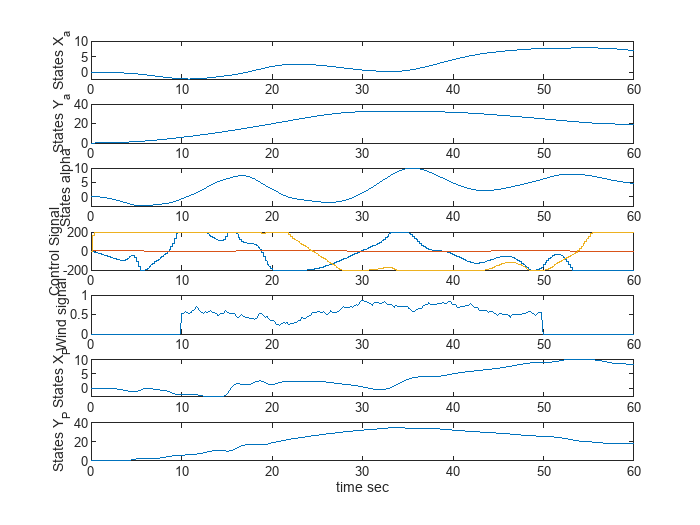

clf
t1 = linspace(0, 60, (60/h));
Xplayload = Xplant(1,:) + l.*sin(Xplant(4,:)).*cos(Xplant(5,:));
Yplayload = Xplant(2,:) + l.*sin(Xplant(4,:)).*sin(Xplant(5,:));



figure(1)
subplot(7,1,1)
plot(t1, Xplant(1,:));
ylabel("States X_a")
subplot(7,1,2)
plot(t1, Xplant(2,:));
ylabel("States Y_a")
subplot(7,1,3)
plot(t1, rad2deg(Xplant(4,:)));
ylabel("States alpha")
subplot(7,1,4)
stairs(t1, u(1,:));
hold on
stairs(t1, u(2,:));
stairs(t1, u(3,:));
ylabel("Control Signal")
hold off
subplot(7,1,5)
plot(t1, W);
ylabel("Wind signal")
subplot(7,1,6)
plot(t1, Xplayload);
ylabel("States X_P")
subplot(7,1,7)
plot(t1, Yplayload);
ylabel("States Y_P")
xlabel("time sec")


% subplot(5,1,5)
% stairs(t, duPlot(1,:));
% ylabel("\Delta u")
% xlabel("Time")

exportgraphics(gcf,'MPC_RenderXYControMoreWind.pdf','ContentType','vector')